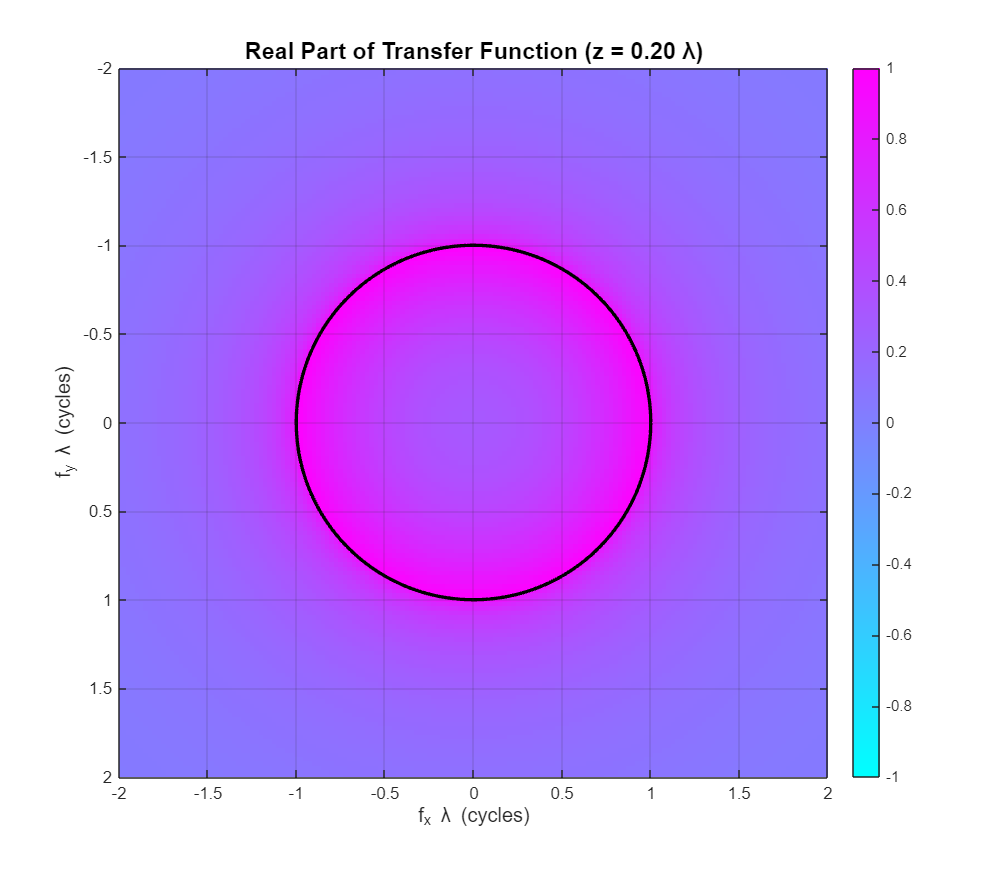

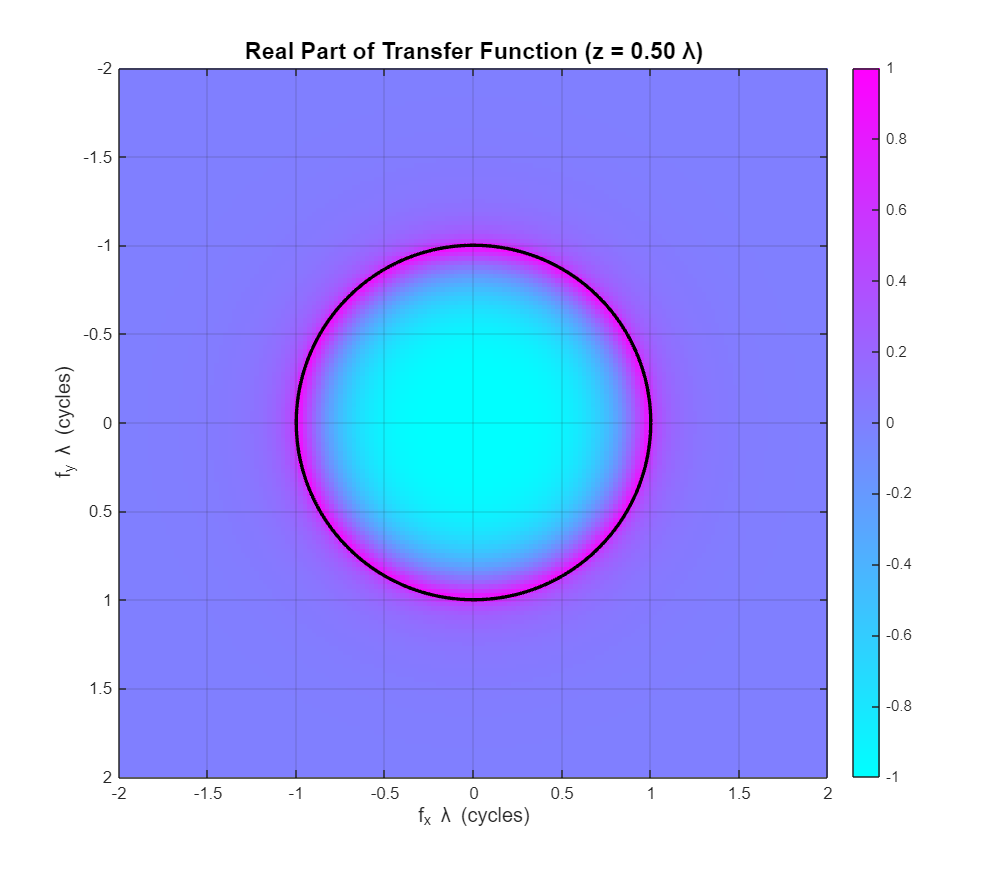

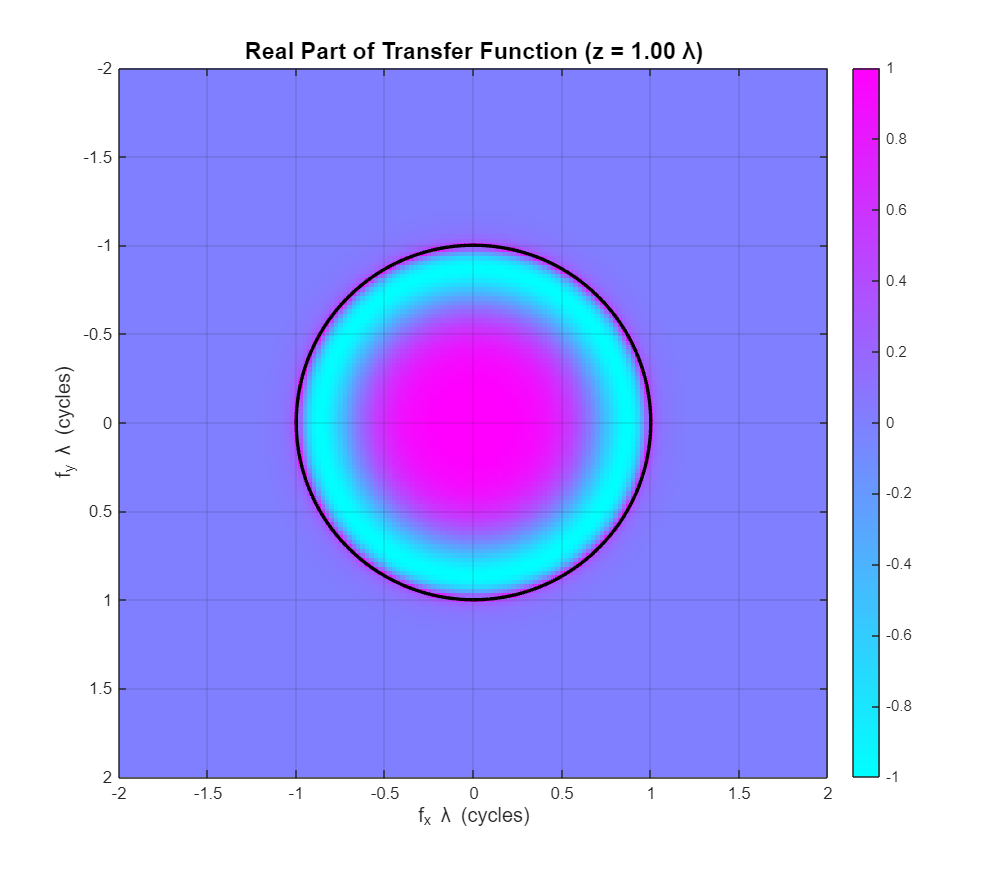

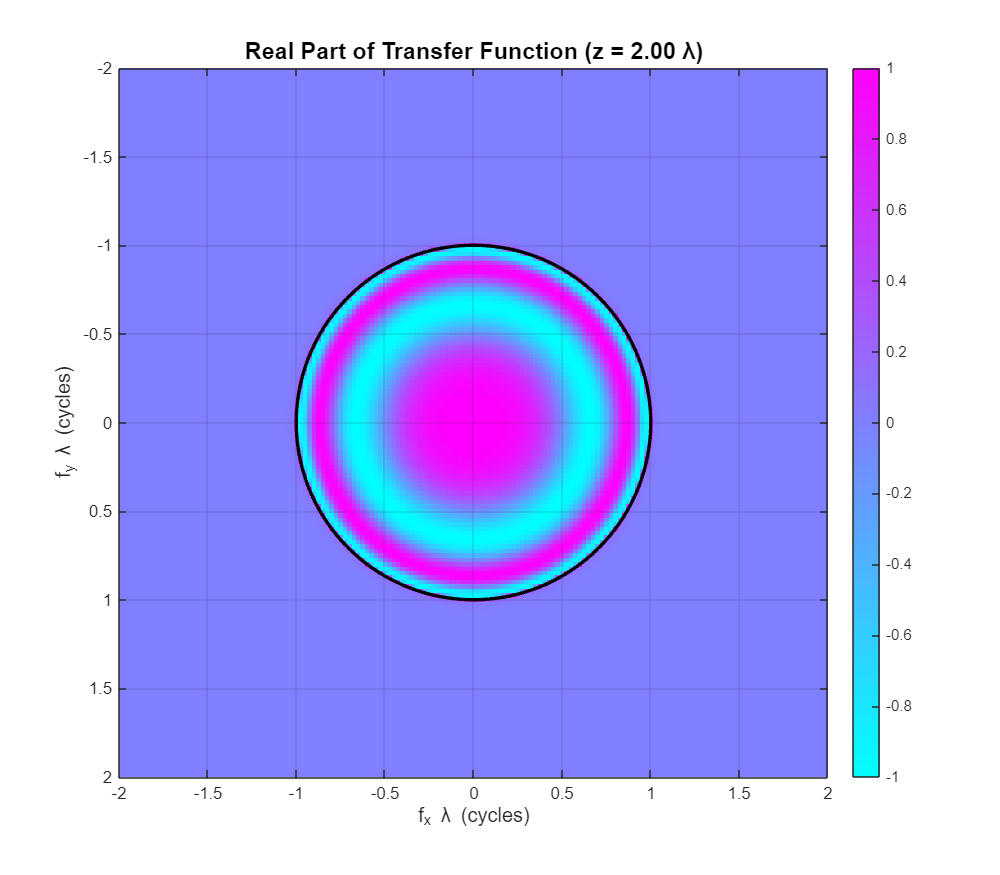

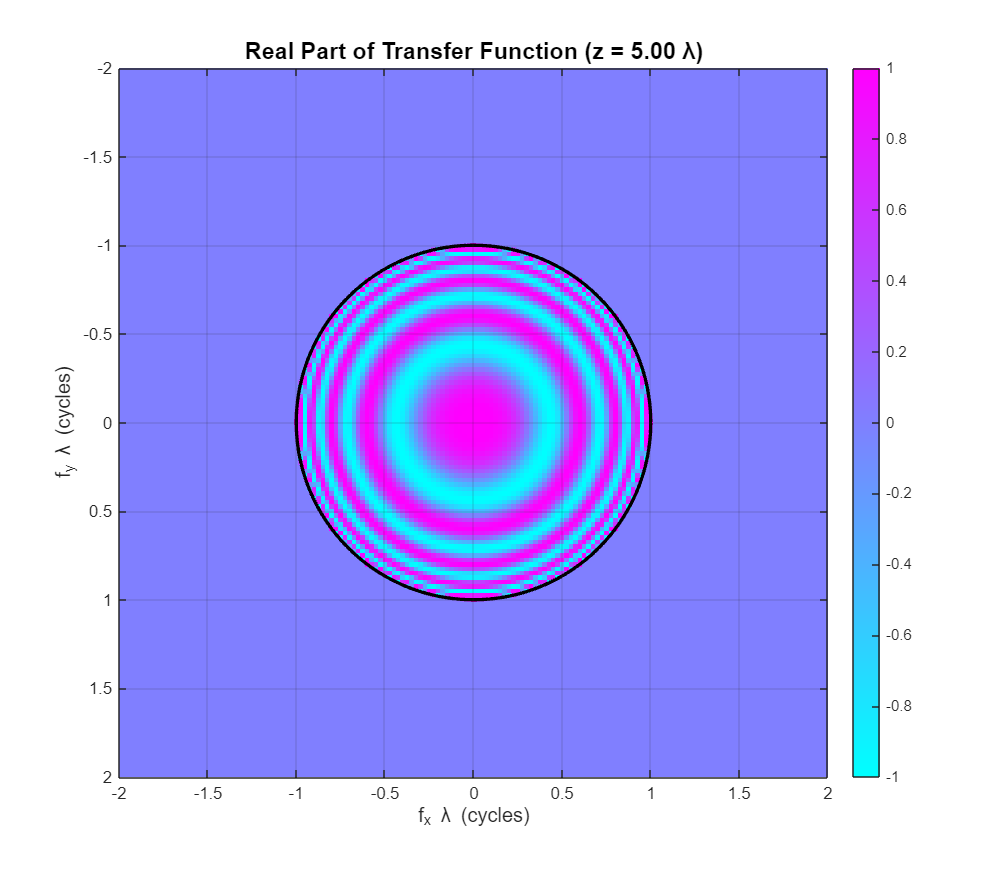

% OPTI 512L 
% LAB 4 WAVES
% MOHANBABU MANI

% 1.

% The free-space transfer function oscillates
% rapidly at higher spatial frequencies and longer propagation distances.

% If the phase variation Δϕ between adjacent frequency samples becomes 
% comparable to or exceeds π radians aliasing occurs.

% This is most likely to happen for large propagation distances (z), 
% high spatial frequencies(f_x,f_y), or insufficient grid resolution (N).

% To propagate farther or examine higher frequencies, grid resolution (N) 
% must be increased or the window size (L) should be reduced to keep 
% the phase gradients below the Nyquist threshold.

lambda = 500e-9;      
k = 2*pi/lambda;        
z_list = [0.2, 0.5, 1, 2, 5] * lambda;  

N = 1024;                
L = 40*lambda;          
fx = (-N/2:N/2-1) / L; 
fy = fx;
[FX,FY] = meshgrid(fx,fy);
fx_norm = fx * lambda;
fy_norm = fy * lambda;
[FX_norm,FY_norm] = meshgrid(fx_norm, fy_norm);

for i = 1:length(z_list)
    z = z_list(i);
    kx = 2*pi*FX;
    ky = 2*pi*FY;
    k_perp_sq = kx.^2 + ky.^2;
    kz = zeros(size(k_perp_sq));
    prop_mask = k_perp_sq < k^2;
    kz(prop_mask) = sqrt(k^2 - k_perp_sq(prop_mask));

    evan_mask = k_perp_sq >= k^2;
    kz(evan_mask) = 1i * sqrt(k_perp_sq(evan_mask) - k^2);
    H = exp(1i * kz * z);
    H_real = real(H);

    figure('Position',[100*i,100*i,800,700]);
    imagesc(fx_norm, fy_norm, H_real);
    axis equal tight;
    title(sprintf('Real Part of Transfer Function (z = %.2f λ)', z/lambda), 'FontSize', 14, 'FontWeight', 'bold');
    xlabel('f_x λ (cycles)', 'FontSize', 12); ylabel('f_y λ (cycles)', 'FontSize', 12);
    colorbar; colormap('cool');
    caxis([-1, 1]);

    hold on;
    theta = linspace(0, 2*pi, 200);
    plot(cos(theta), sin(theta), 'k-', 'LineWidth', 2);
    hold off;

    xlim([-2, 2]); ylim([-2, 2]);
    grid on;
end

% 2.

% To calculate Free-Space Transfer Function
% H(fx,fy,z) = exp(i*k*z*sqrt(1-(λfx)²-(λfy)²))
% In near field (z < λ), object maintains sharp edges.
% Intermediate (z ≈ λ), Fresnel diffraction patterns emerge.
% Far field (z > 2λ), Pronounced diffraction spreading.
% Sharp edges create oscillatory interference patterns.
% Wave spreads beyond geometric shadow boundaries.

lambda = 500e-9;        
k = 2*pi/lambda;         
z_distances = [0.2, 0.5, 1.0, 2.0, 3.0] * lambda;
N = 512;                 
L = 30 * lambda;        
dx = L / N;              
dy = dx;         
x = (-N/2:N/2-1) * dx;   
y = (-N/2:N/2-1) * dy;   
[X, Y] = meshgrid(x, y);

dfx = 1/L;               
dfy = 1/L;
fx = (-N/2:N/2-1) * dfx; 
fy = (-N/2:N/2-1) * dfy;
[FX, FY] = meshgrid(fx, fy);

fprintf('Grid size: %d x %d points\n', N, N);

Grid size: 512 x 512 points


fprintf('Physical window: %.1f x %.1f μm\n', L*1e6, L*1e6);

Physical window: 15.0 x 15.0 μm


fprintf('Pixel size: %.2f nm\n', dx*1e9);

Pixel size: 29.30 nm


fprintf('Max spatial frequency: %.2f cycles/μm\n', max(fx)*1e-6);

Max spatial frequency: 17.00 cycles/μm



rect_width = 8 * lambda;  
rect_height = 6 * lambda;  
rectangular_aperture = (abs(X) <= rect_width/2) & (abs(Y) <= rect_height/2);
circle_radius = 5 * lambda;
circular_aperture = sqrt(X.^2 + Y.^2) <= circle_radius;

object_choice = 1;

if object_choice == 1
    U_object = double(rectangular_aperture);
    object_name = 'Rectangular Aperture';
    object_size = sprintf('%.1f × %.1f μm', rect_width*1e6, rect_height*1e6);
else
    U_object = double(circular_aperture);
    object_name = 'Circular Aperture';
    object_size = sprintf('radius = %.1f μm', circle_radius*1e6);
end

U0 = U_object;  

fprintf('Object type: %s\n', object_name);

Object type: Rectangular Aperture


fprintf('Object size: %s\n', object_size);

Object size: 4.0 × 3.0 μm


fprintf('Object area: %.1f λ²\n', sum(U_object(:)) * (dx^2) / lambda^2);

Object area: 48.4 λ²


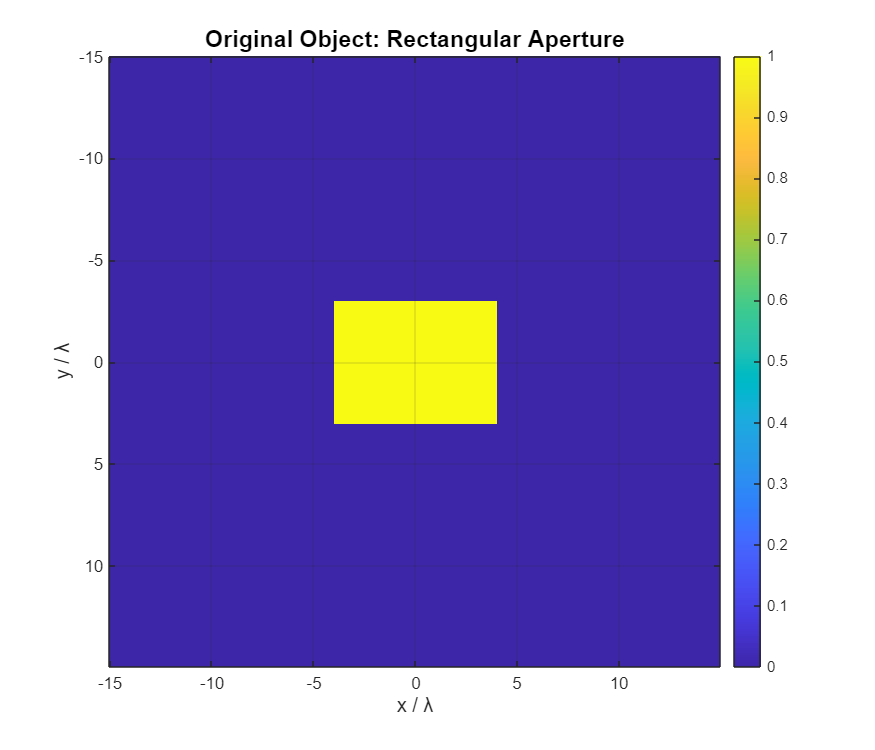


figure('Position', [100, 100, 700, 600]);
imagesc(x/lambda, y/lambda, abs(U0).^2);
axis equal tight;
title(sprintf('Original Object: %s', object_name), 'FontSize', 14, 'FontWeight', 'bold');
xlabel('x / λ', 'FontSize', 12);
ylabel('y / λ', 'FontSize', 12);
colorbar;
colormap('parula');
grid on;

Beam width (FWHM): 3.81 μm (7.62 λ)


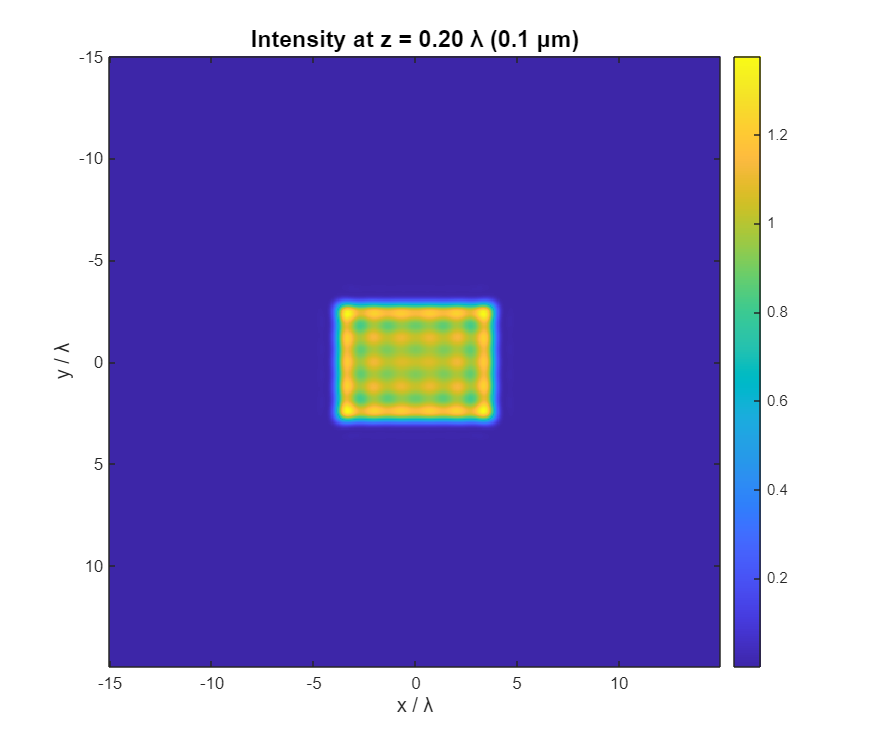

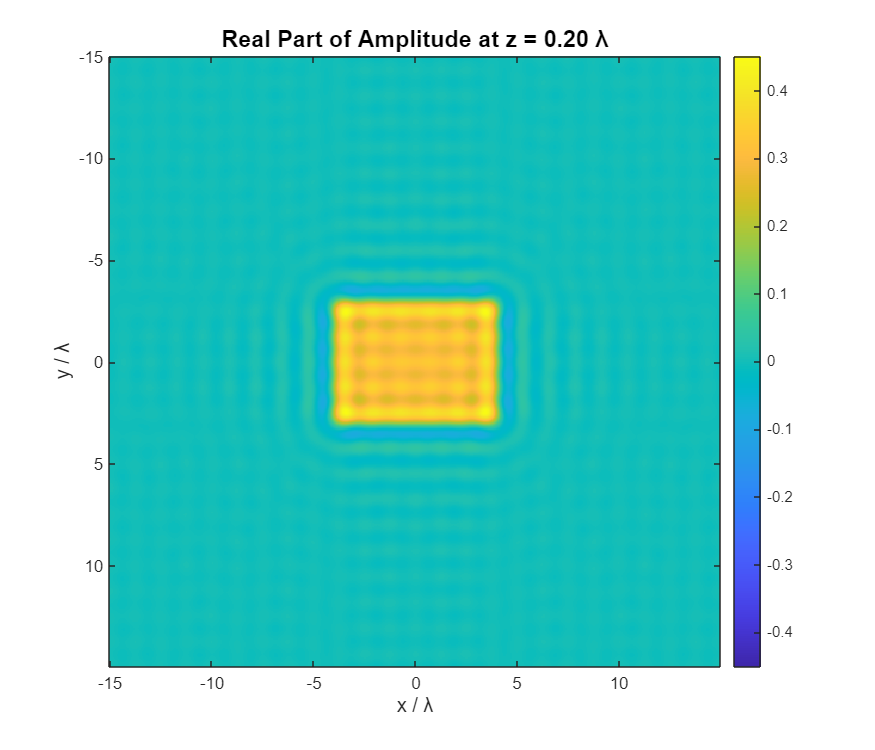

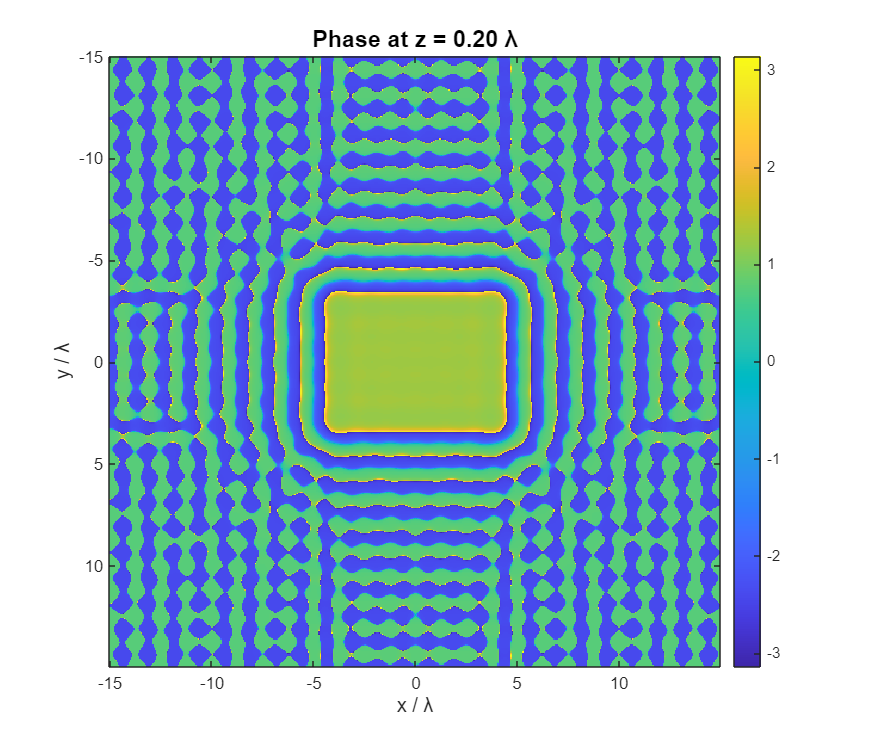

Beam width (FWHM): 3.81 μm (7.62 λ)


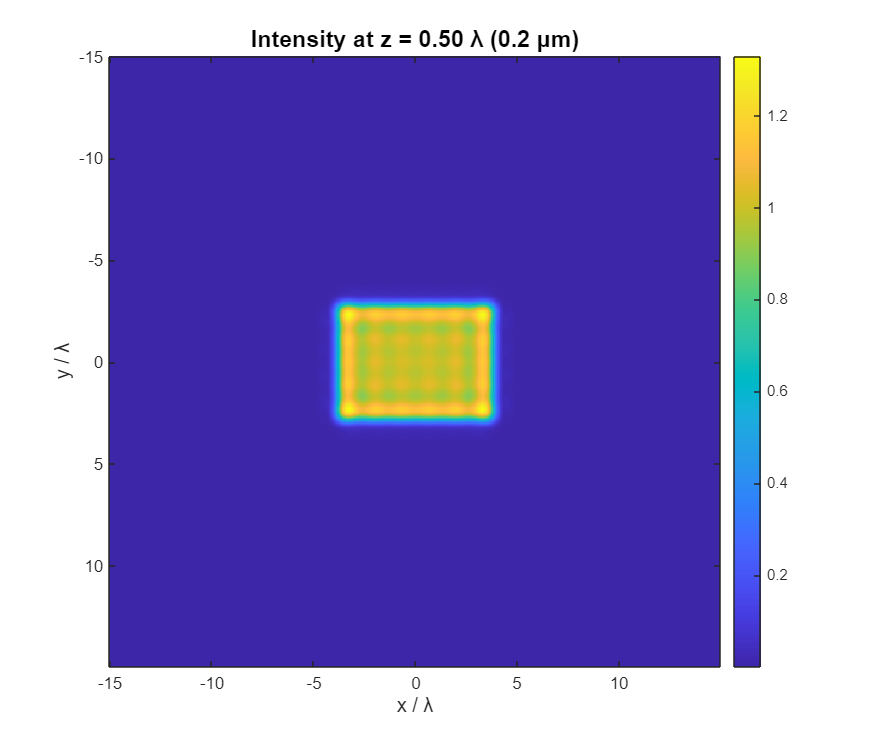

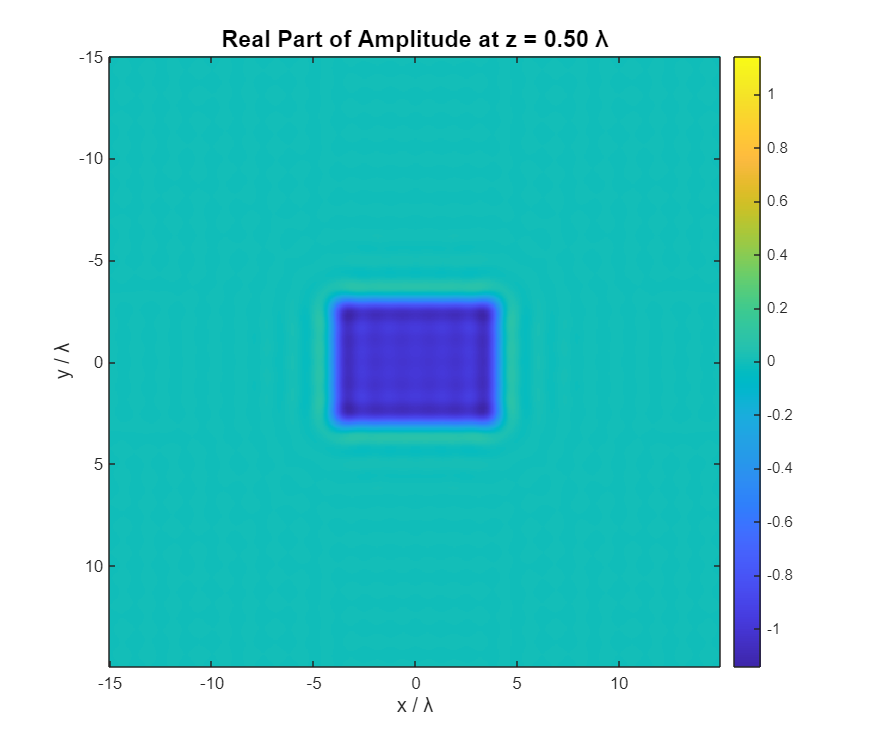

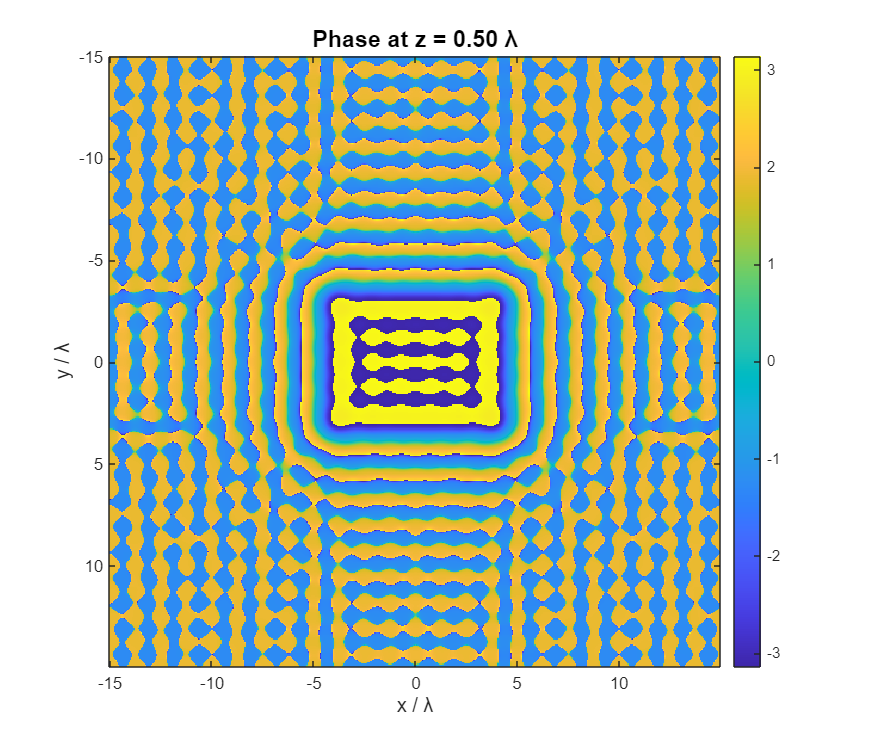

Beam width (FWHM): 3.75 μm (7.50 λ)


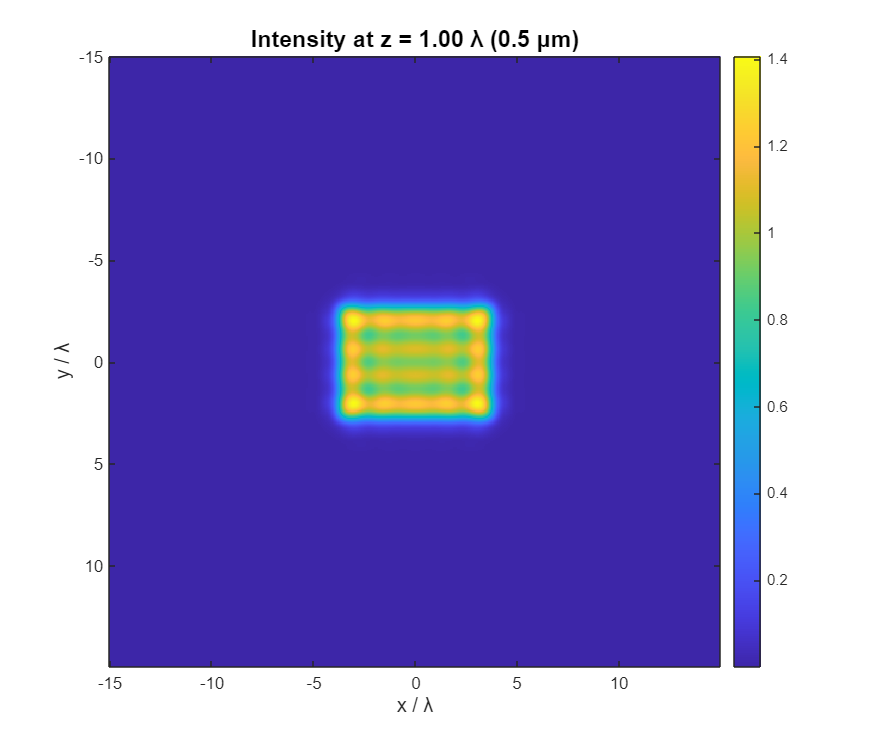

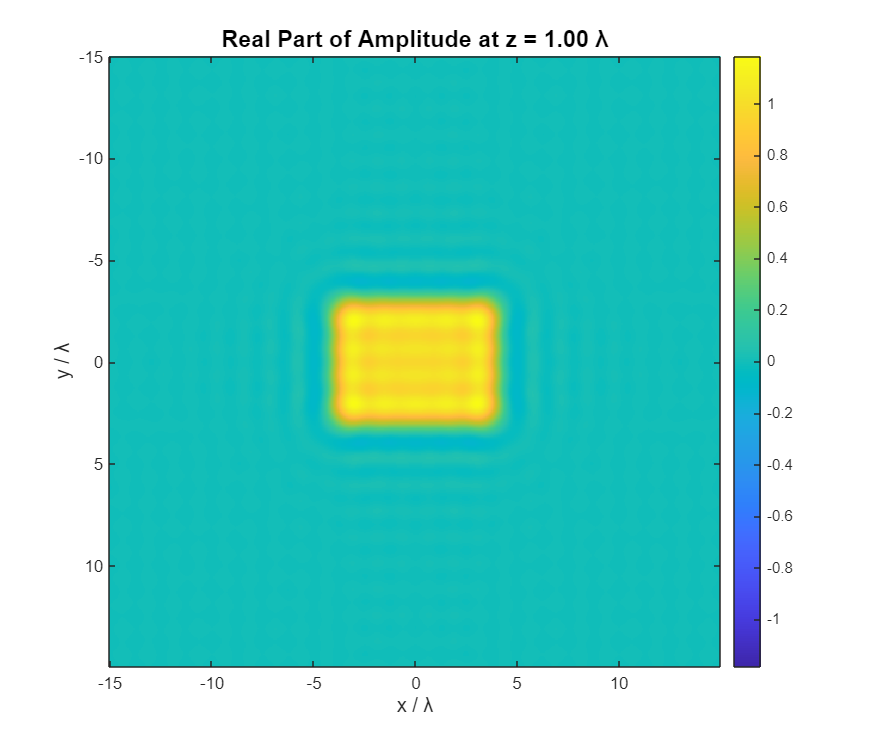

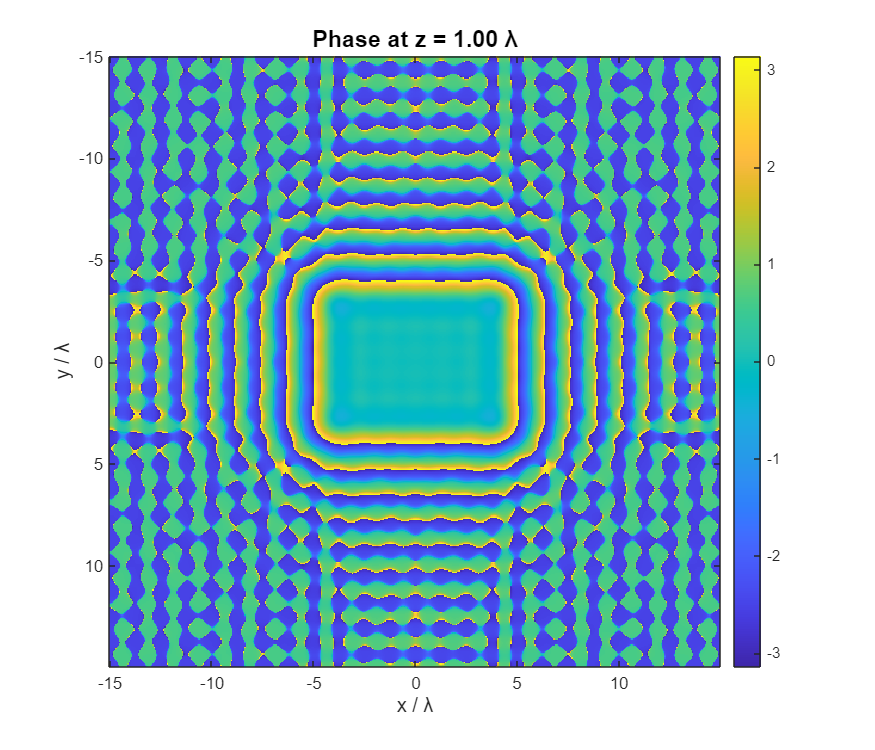

Beam width (FWHM): 3.46 μm (6.91 λ)


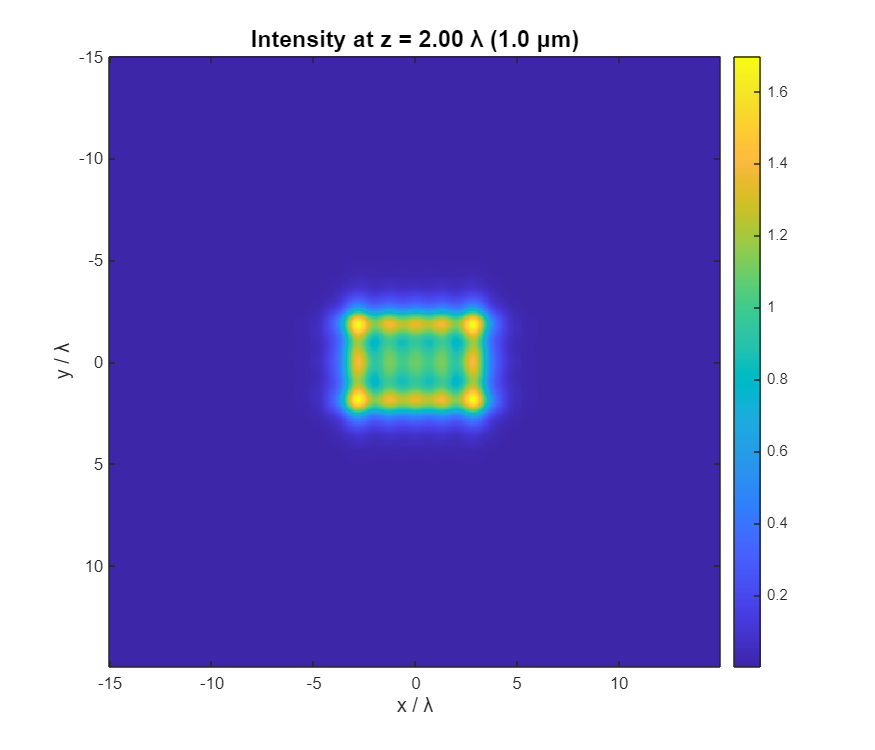

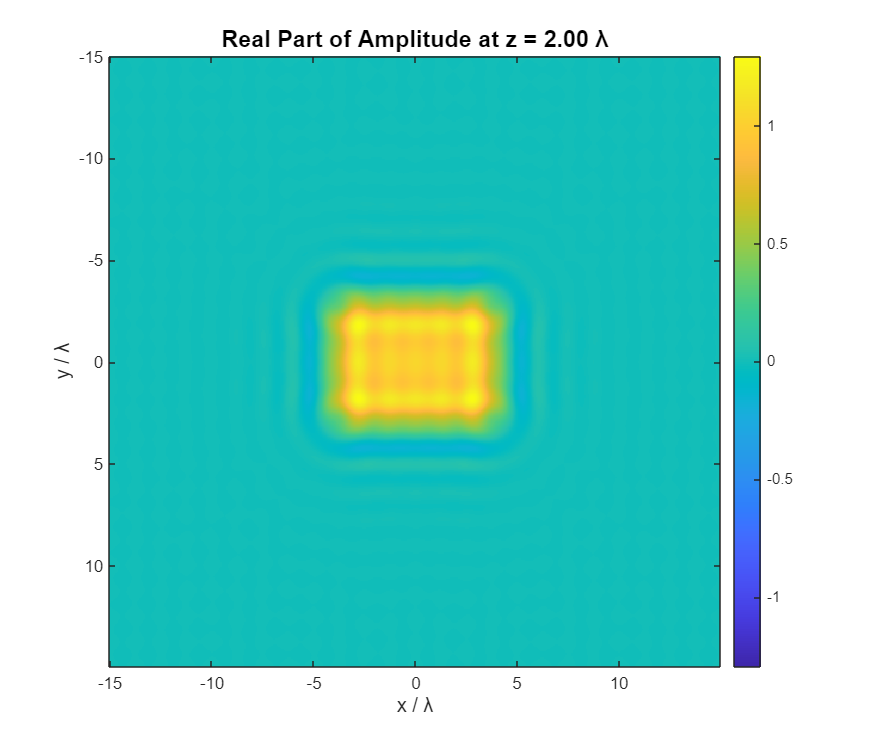

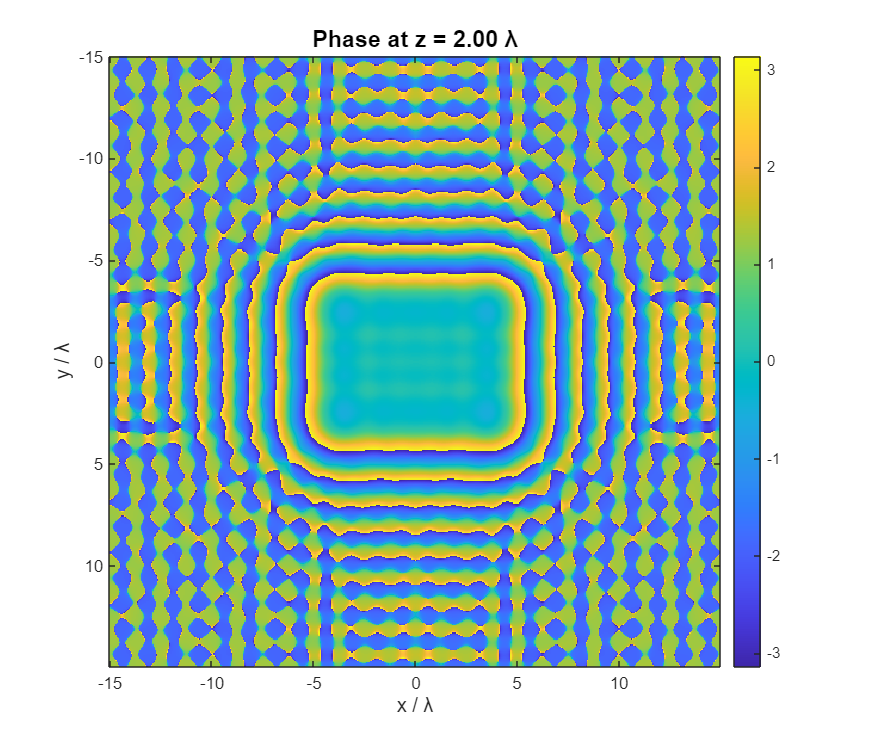

Beam width (FWHM): 3.34 μm (6.68 λ)


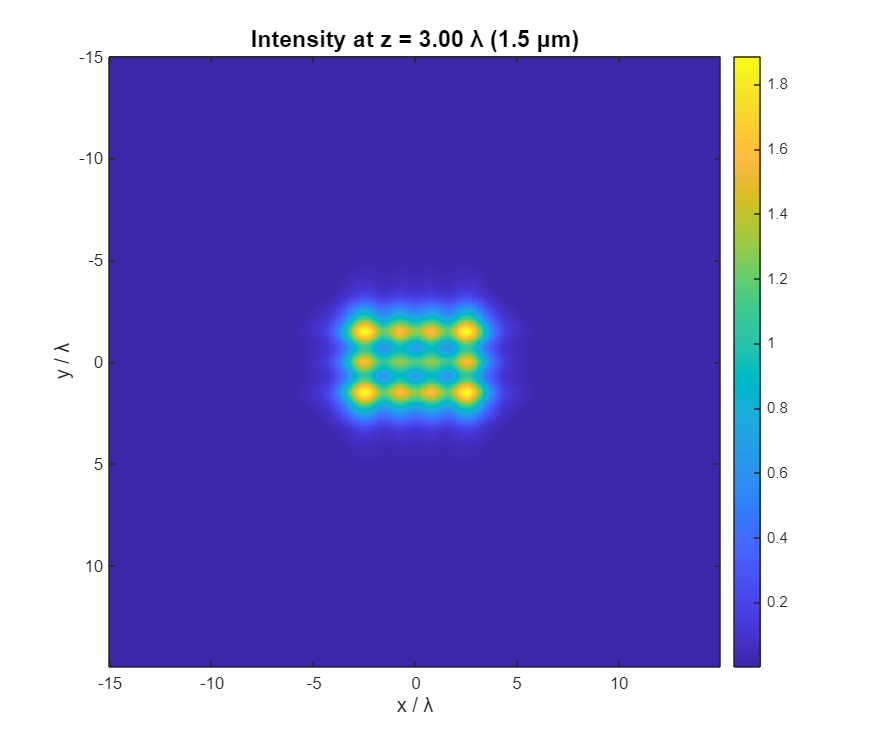

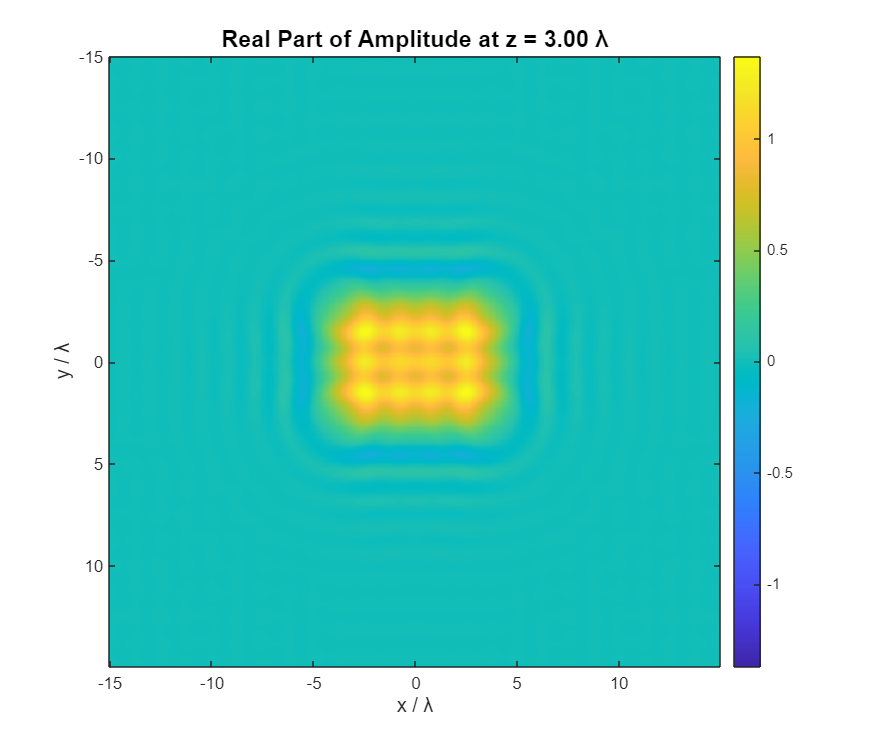

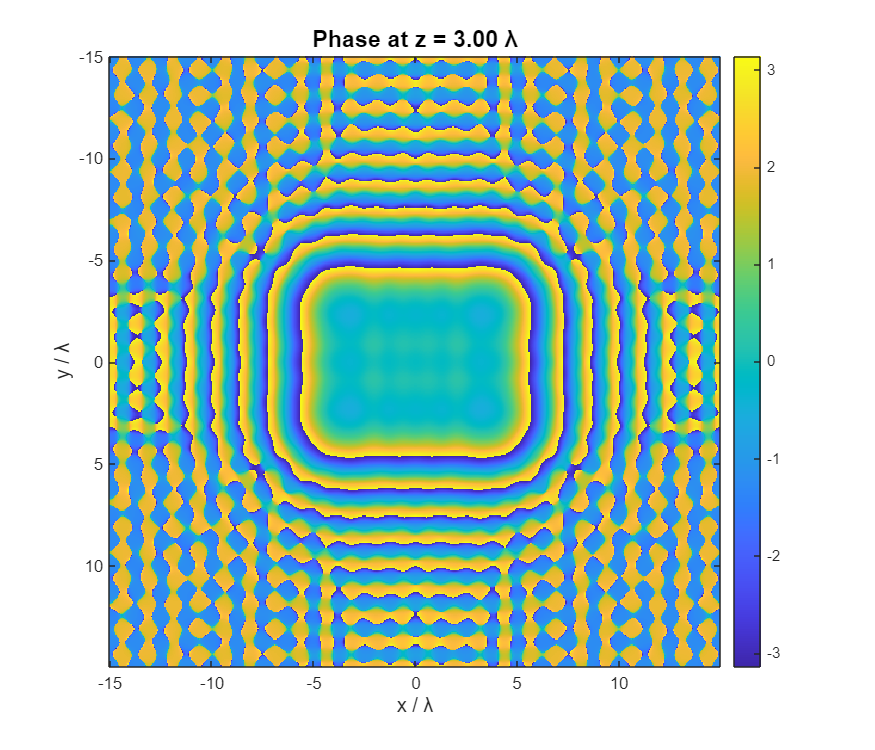


for i = 1:length(z_distances)
    z = z_distances(i);
    kx = 2*pi*FX;            
    ky = 2*pi*FY;            
    k_perp_squared = kx.^2 + ky.^2; 
    kz = zeros(size(k_perp_squared));
    propagating_mask = k_perp_squared < k^2;
    kz(propagating_mask) = sqrt(k^2 - k_perp_squared(propagating_mask));
    evanescent_mask = k_perp_squared >= k^2;
    kz(evanescent_mask) = 1i * sqrt(k_perp_squared(evanescent_mask) - k^2);
    H = exp(1i * kz * z);
    max_freq = 0.8 * k / (2*pi);  
    freq_magnitude = sqrt(FX.^2 + FY.^2);
    filter_mask = freq_magnitude <= max_freq;
    H = H .* filter_mask;
    
    propagating_fraction = sum(propagating_mask(:)) / numel(propagating_mask);
    U0_spectrum = fftshift(fft2(ifftshift(U0)));
    U_propagated_spectrum = U0_spectrum .* H;
    U_propagated = fftshift(ifft2(ifftshift(U_propagated_spectrum)));
    I_propagated = abs(U_propagated).^2;   
    phase_propagated = angle(U_propagated); 
    energy_initial = sum(abs(U0(:)).^2) * dx^2;
    energy_propagated = sum(abs(U_propagated(:)).^2) * dx^2;
    energy_ratio = energy_propagated / energy_initial;
    center_y = round(N/2) + 1;
    intensity_cross_section = I_propagated(center_y, :);
    max_intensity = max(intensity_cross_section);
    half_max_indices = find(intensity_cross_section >= max_intensity/2);
    if ~isempty(half_max_indices)
        beam_width = (max(half_max_indices) - min(half_max_indices)) * dx;
        fprintf('Beam width (FWHM): %.2f μm (%.2f λ)\n', beam_width*1e6, beam_width/lambda);
    end
   
    figure('Position', [150 + 50*i, 150 + 50*i, 700, 600]);
    imagesc(x/lambda, y/lambda, I_propagated);
    axis equal tight;
    title(sprintf('Intensity at z = %.2f λ (%.1f μm)', z/lambda, z*1e6), ...
          'FontSize', 14, 'FontWeight', 'bold');
    xlabel('x / λ', 'FontSize', 12);
    ylabel('y / λ', 'FontSize', 12);
    colorbar;
    colormap('parula');

    figure('Position', [200 + 50*i, 200 + 50*i, 700, 600]);
    imagesc(x/lambda, y/lambda, real(U_propagated));
    axis equal tight;
    title(sprintf('Real Part of Amplitude at z = %.2f λ', z/lambda), ...
          'FontSize', 14, 'FontWeight', 'bold');
    xlabel('x / λ', 'FontSize', 12);
    ylabel('y / λ', 'FontSize', 12);
    colorbar;
    colormap('parula');
    
    max_amplitude = max(abs(real(U_propagated(:))));
    caxis([-max_amplitude, max_amplitude]);
    
    figure('Position', [250 + 50*i, 250 + 50*i, 700, 600]);
    imagesc(x/lambda, y/lambda, phase_propagated);
    axis equal tight;
    title(sprintf('Phase at z = %.2f λ', z/lambda), ...
          'FontSize', 14, 'FontWeight', 'bold');
    xlabel('x / λ', 'FontSize', 12);
    ylabel('y / λ', 'FontSize', 12);
    colorbar;
    colormap('parula');
    caxis([-pi, pi]);
end

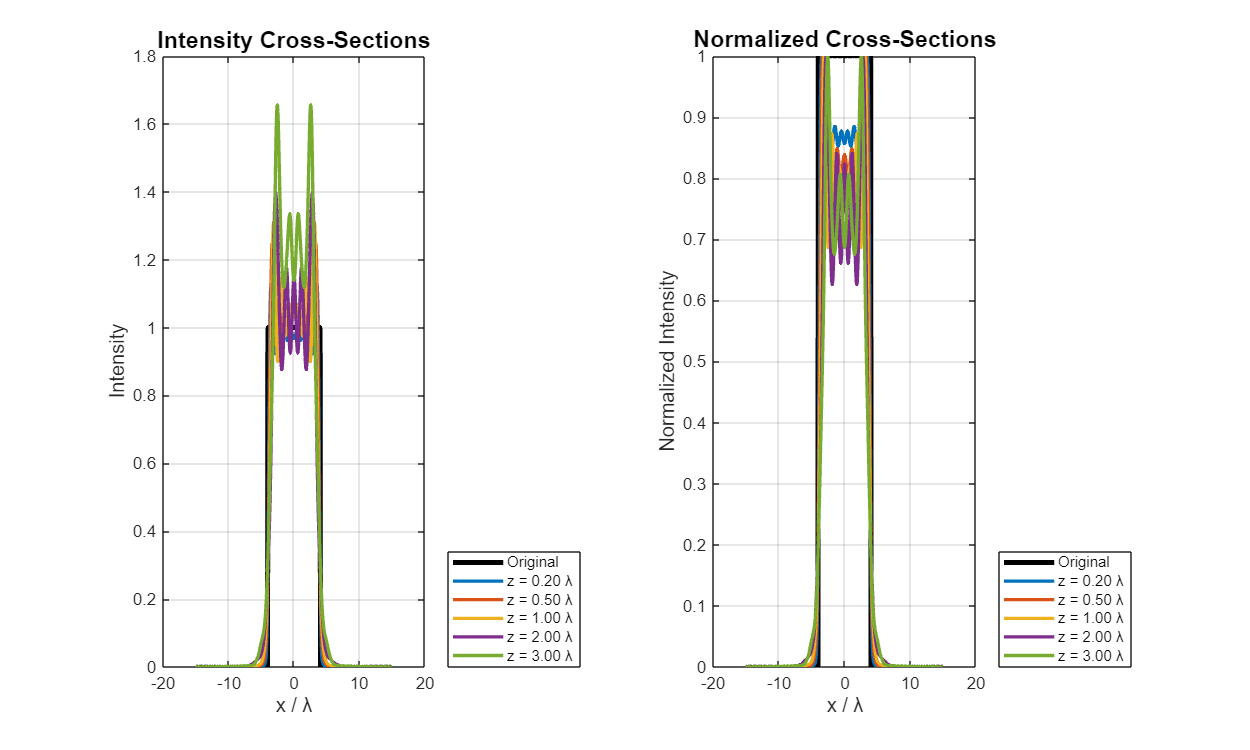


figure('Position', [300, 300, 1000, 600]);
subplot(1, 2, 1);
colors = lines(length(z_distances));
center_y = round(N/2) + 1;
I0_cross = abs(U0(center_y, :)).^2;
plot(x/lambda, I0_cross, 'k-', 'LineWidth', 3, 'DisplayName', 'Original');
hold on;

for i = 1:length(z_distances)
    z = z_distances(i);
    kx = 2*pi*FX;
    ky = 2*pi*FY;
    k_perp_squared = kx.^2 + ky.^2;
    kz = zeros(size(k_perp_squared));
    propagating_mask = k_perp_squared < k^2;
    kz(propagating_mask) = sqrt(k^2 - k_perp_squared(propagating_mask));
    evanescent_mask = k_perp_squared >= k^2;
    kz(evanescent_mask) = 1i * sqrt(k_perp_squared(evanescent_mask) - k^2);
    H = exp(1i * kz * z);
    U0_spectrum = fftshift(fft2(ifftshift(U0)));
    U_prop_spectrum = U0_spectrum .* H;
    U_prop = fftshift(ifft2(ifftshift(U_prop_spectrum)));
    I_prop_cross = abs(U_prop(center_y, :)).^2;
    plot(x/lambda, I_prop_cross, 'Color', colors(i,:), 'LineWidth', 2, ...
         'DisplayName', sprintf('z = %.2f λ', z/lambda));
end

xlabel('x / λ', 'FontSize', 12);
ylabel('Intensity', 'FontSize', 12);
title('Intensity Cross-Sections', 'FontSize', 14);
legend('Location', 'southeastoutside');
grid on;

subplot(1, 2, 2);
plot(x/lambda, I0_cross/max(I0_cross), 'k-', 'LineWidth', 3, 'DisplayName', 'Original');
hold on;

for i = 1:length(z_distances)
    z = z_distances(i);
    kx = 2*pi*FX;
    ky = 2*pi*FY;
    k_perp_squared = kx.^2 + ky.^2;
    kz = zeros(size(k_perp_squared));
    propagating_mask = k_perp_squared < k^2;
    kz(propagating_mask) = sqrt(k^2 - k_perp_squared(propagating_mask));
    evanescent_mask = k_perp_squared >= k^2;
    kz(evanescent_mask) = 1i * sqrt(k_perp_squared(evanescent_mask) - k^2);
    H = exp(1i * kz * z);
    U0_spectrum = fftshift(fft2(ifftshift(U0)));
    U_prop_spectrum = U0_spectrum .* H;
    U_prop = fftshift(ifft2(ifftshift(U_prop_spectrum)));
    I_prop_cross = abs(U_prop(center_y, :)).^2;
    plot(x/lambda, I_prop_cross/max(I_prop_cross), 'Color', colors(i,:), 'LineWidth', 2, ...
         'DisplayName', sprintf('z = %.2f λ', z/lambda));
end

xlabel('x / λ', 'FontSize', 12);
ylabel('Normalized Intensity', 'FontSize', 12);
title('Normalized Cross-Sections', 'FontSize', 14);
legend('Location', 'southeastoutside');
grid on;

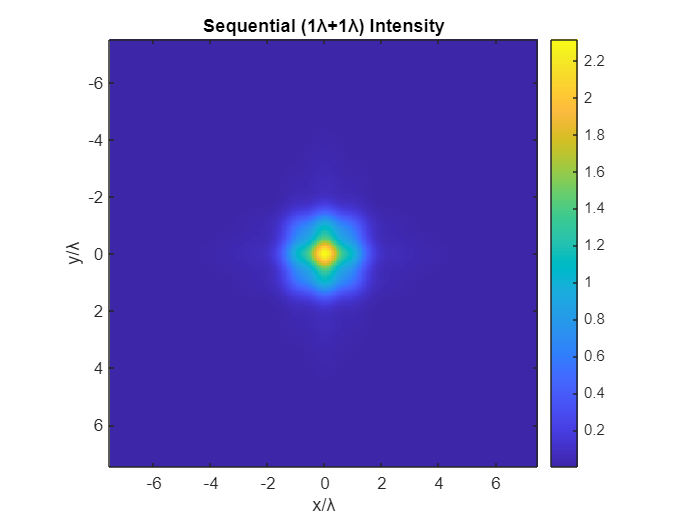

% 3.

% After propagating 1 λ then another 1 λ, the complex amplitude U_seq and intensity 
% ∣U_seq∣^2 are indistinguishable from the field U_direct 
% obtained by a single 2 λ propagation.

% Cross‐section plots of ∣U∣ overlap perfectly for both methods.

lambda = 500e-9;           
k      = 2*pi/lambda;        
z_step = lambda;             
z_total = 2*lambda;          
N = 256;                   
L = 15*lambda;              
dx = L/N;                   
x  = (-N/2:N/2-1)*dx;       
y  = x;
[FX,FY] = meshgrid((-N/2:N/2-1)/L, (-N/2:N/2-1)/L); 
a = 3*lambda;             
[X,Y] = meshgrid(x,y);
U0 = double(abs(X)<=a/2 & abs(Y)<=a/2);

function H = transferFcn(FX,FY,k, z, lambda)
    kx = 2*pi*FX;
    ky = 2*pi*FY;
    K2 = kx.^2 + ky.^2;
    kz = sqrt(max(0, k^2 - K2)) + 1i*sqrt(max(0, K2 - k^2));
    H  = exp(1i*kz*z);
end

function Uout = propagate(Uin, H)
    U_fft = fftshift(fft2(ifftshift(Uin)));
    Uout  = fftshift(ifft2(ifftshift(U_fft.*H)));
end

H1 = transferFcn(FX,FY,k, z_step, lambda);
U1 = propagate(U0, H1);
H2 = transferFcn(FX,FY,k, z_step, lambda);
U_seq = propagate(U1, H2);

Hdir = transferFcn(FX,FY,k, z_total, lambda);
U_dir = propagate(U0, Hdir);

diffU = U_seq - U_dir;
relErr = max(abs(diffU(:))) / max(abs(U_dir(:)));

figure; imagesc(x/lambda,y/lambda,abs(U_seq).^2); axis image; colormap parula;
title('Sequential (1λ+1λ) Intensity'); xlabel('x/λ'); ylabel('y/λ'); colorbar;

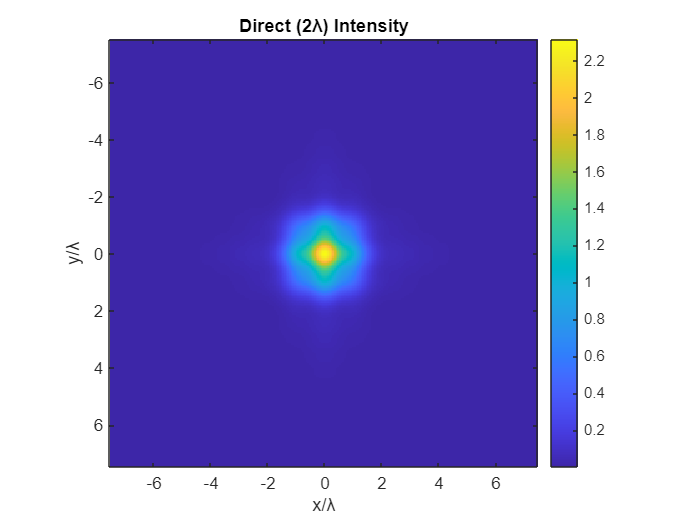


figure; imagesc(x/lambda,y/lambda,abs(U_dir).^2); axis image; colormap parula;
title('Direct (2λ) Intensity'); xlabel('x/λ'); ylabel('y/λ'); colorbar;

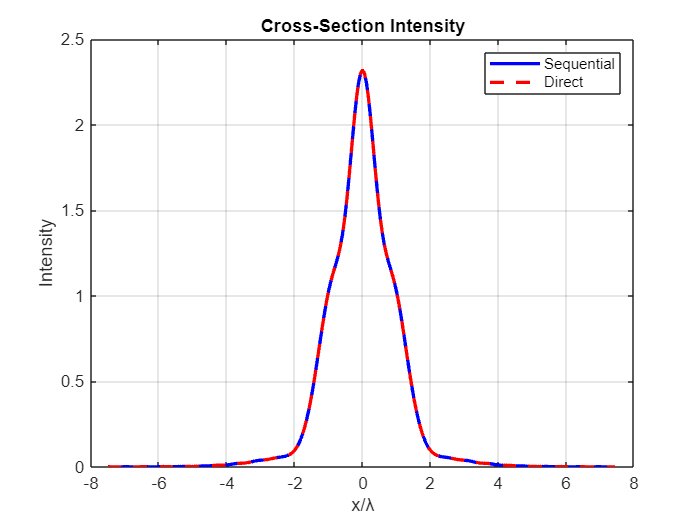


mid = N/2 + 1;
figure; 
plot(x/lambda, abs(U_seq(mid,:)).^2,'b-','LineWidth',2); hold on;
plot(x/lambda, abs(U_dir(mid,:)).^2,'r--','LineWidth',2);
xlabel('x/λ'); ylabel('Intensity'); title('Cross-Section Intensity');
legend('Sequential','Direct'); grid on;

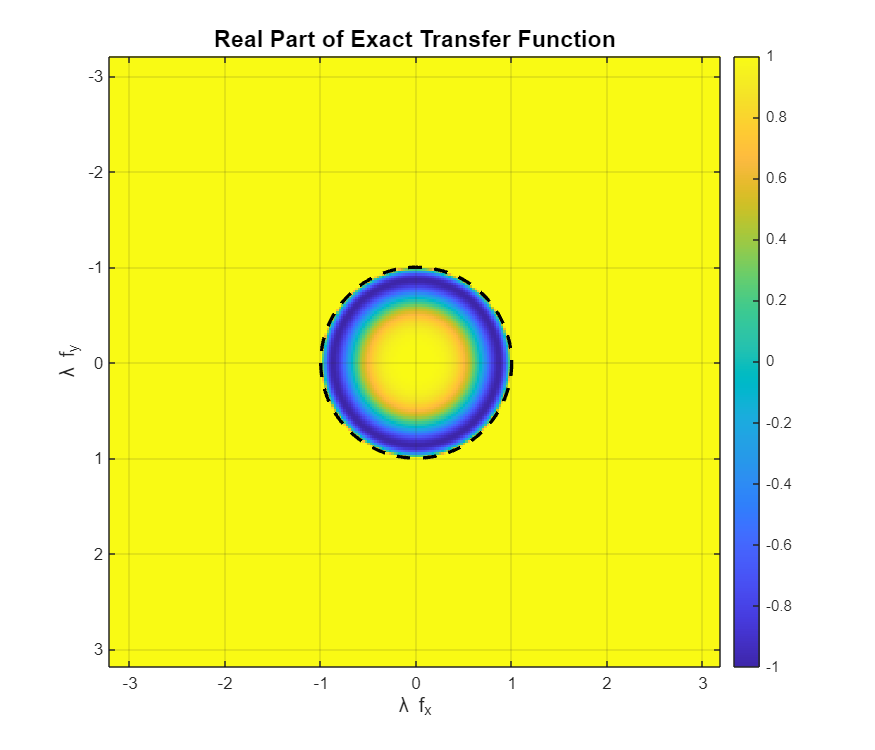

% 4.


lambda = 500e-9;      
k  = 2*pi/lambda;    
z  = 1 * lambda;     
N = 256;                 
L = 40 * lambda;         
dx = L / N;              
fx = (-N/2:N/2-1) / L;
fy = fx;
[FX, FY] = meshgrid(fx, fy);
fx_norm = fx * lambda;
fy_norm = fy * lambda;
R2 = (fx_norm.^2).' + fy_norm.^2;  
valid = R2 < 1;                    

[FXn, FYn] = meshgrid(fx_norm, fy_norm);
kz_exact = sqrt(max(0, 1 - FXn.^2 - FYn.^2));
H_exact = exp(1i * k * z * kz_exact);

[FXg, FYg] = meshgrid(fx, fy);
H_paraxial = exp(1i * k * z) ...
           .* exp(-1i * pi * lambda * z * (FXg.^2 + FYg.^2));

H_ex_real = real(H_exact);
H_px_real = real(H_paraxial);
H_diff    = H_ex_real - H_px_real;

figure('Position',[100,100,700,600]);
imagesc(fx_norm, fy_norm, H_ex_real);
axis image;
colormap('parula'); colorbar;
caxis([-1 1]);
title('Real Part of Exact Transfer Function','FontSize',14);
xlabel('λ f_x','FontSize',12);
ylabel('λ f_y','FontSize',12);
hold on;
theta = linspace(0,2*pi,200);
plot(cos(theta), sin(theta),'k--','LineWidth',2);  % |f|λ=1
hold off;
grid on;

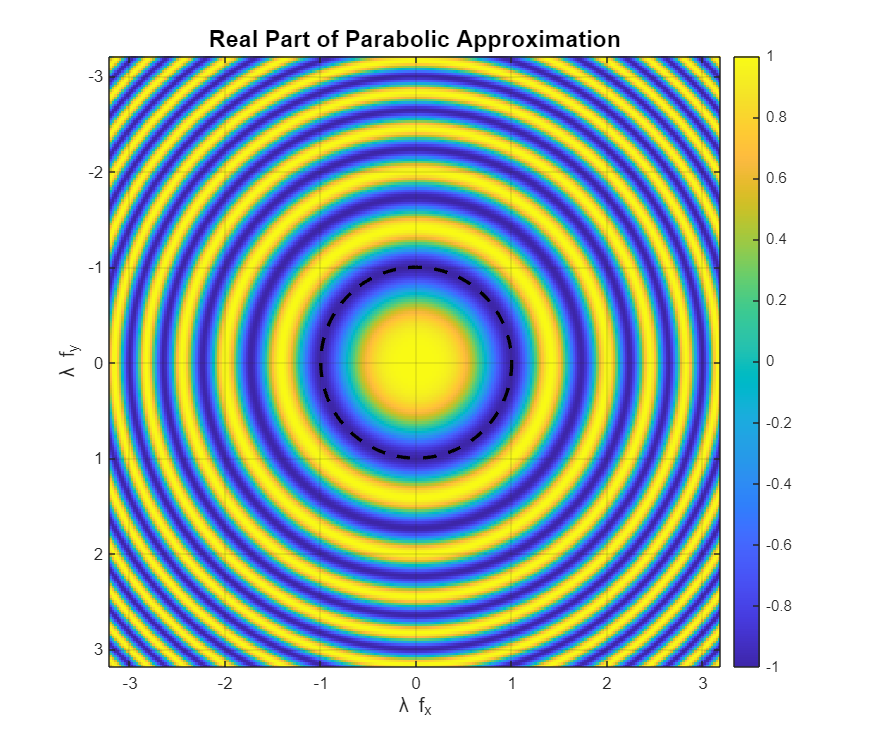


figure('Position',[200,200,700,600]);
imagesc(fx_norm, fy_norm, H_px_real);
axis image;
colormap('parula'); colorbar;
caxis([-1 1]);
title('Real Part of Parabolic Approximation','FontSize',14);
xlabel('λ f_x','FontSize',12);
ylabel('λ f_y','FontSize',12);
hold on;
plot(cos(theta), sin(theta),'k--','LineWidth',2);
hold off;
grid on;

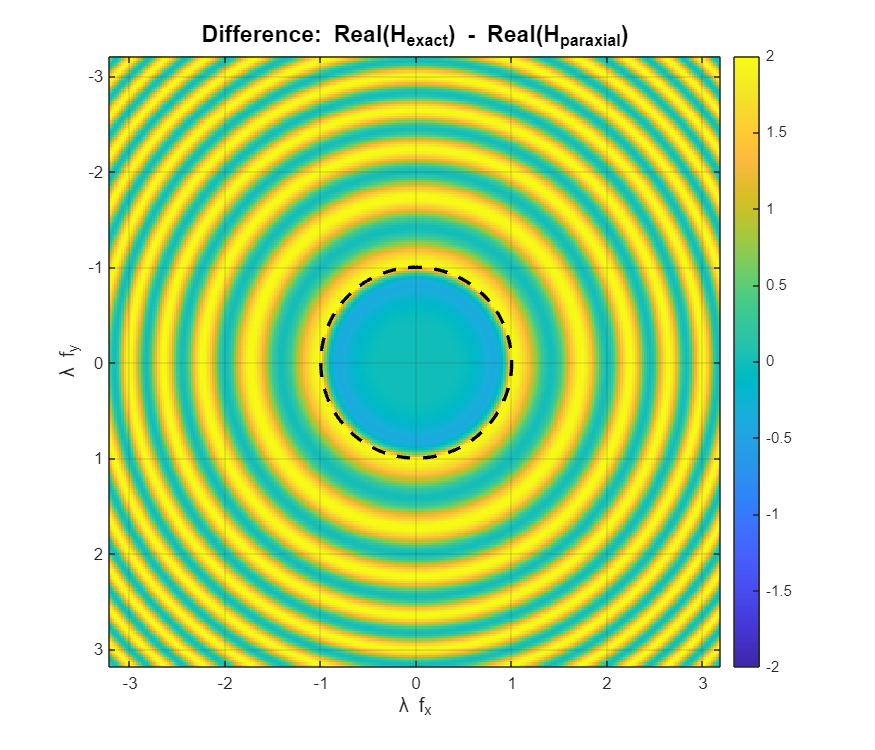


figure('Position',[300,300,700,600]);
imagesc(fx_norm, fy_norm, H_diff);
axis image;
colormap('parula'); colorbar;
maxd = max(abs(H_diff(:)));
caxis([-maxd maxd]);
title('Difference: Real(H_{exact}) - Real(H_{paraxial})','FontSize',14);
xlabel('λ f_x','FontSize',12);
ylabel('λ f_y','FontSize',12);
hold on;
plot(cos(theta), sin(theta),'k--','LineWidth',2);
hold off;
grid on;

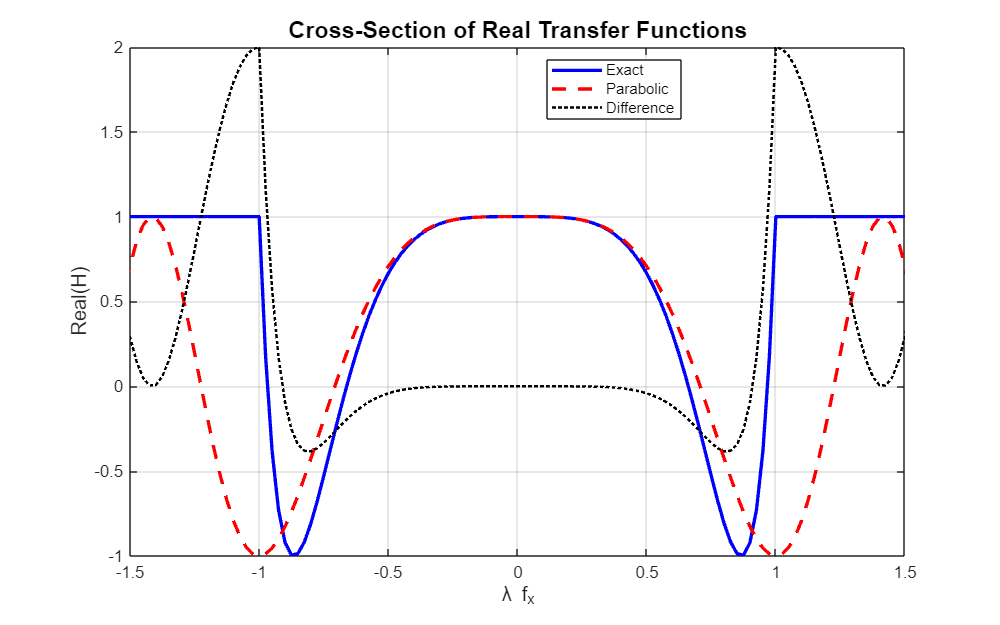


mid = round(N/2)+1;
freq = fx_norm;
exact_cs = H_ex_real(mid, :);
parax_cs = H_px_real(mid, :);
diff_cs  = H_diff(mid, :);

figure('Position',[400,400,800,500]);
plot(freq, exact_cs,'b-','LineWidth',2); hold on;
plot(freq, parax_cs,'r--','LineWidth',2);
plot(freq, diff_cs,'k:','LineWidth',1.5);
xlabel('λ f_x','FontSize',12);
ylabel('Real(H)','FontSize',12);
title('Cross-Section of Real Transfer Functions','FontSize',14);
legend('Exact','Parabolic','Difference','Location','Best');
grid on;
xlim([-1.5 1.5]);